clear; clc; close all;

split_percent = 0.7;
split_idx = size(features, 4) * split_percent;

X_Train = features(:, :, :, 1:split_idx);
Y_Train = labels(:, 1:split_idx);
X_Test = features(:, :, :, split_idx+1:end);
Y_Test = labels(:, split_idx+1:end);

#### Sigmoid (optional)

Applying sigmoid can be used as a normalization

X_Train = dlarray(X_Train);
X_Test = dlarray(X_Test);
X_Train = 2 * sigmoid(X_Train) - 1;
X_Test = 2 * sigmoid(X_Test) - 1;
X_Train = extractdata(X_Train);
X_Test = extractdata(X_Test);

dsTrain = CRN_DataStore(X_Train, Y_Train);
dsTest = CRN_DataStore(X_Test, Y_Test);
dsTrain, dsTest

dsTrain =   CRN_DataStore with properties:

    Features: [4×4×2×840000 double]
      Labels: [14×840000 double]


dsTest =   CRN_DataStore with properties:

    Features: [4×4×2×360000 double]
      Labels: [14×360000 double]


M = size(X_Train, 1);
N = size(Y_Train, 1) / 2;

layers_CRN = [
    imageInputLayer([M M 2], "Normalization", "none")
    convolution2dLayer(2, 128, "Stride", 1, "Padding", 0)
    batchNormalizationLayer
    leakyReluLayer
    convolution2dLayer(2, 128, "Stride", 1, "Padding", 0)
    batchNormalizationLayer
    leakyReluLayer
    convolution2dLayer(2, 128, "Stride", 1, "Padding", 0)
    batchNormalizationLayer
    leakyReluLayer
    flattenLayer
    fullyConnectedLayer(512)
    leakyReluLayer
    dropoutLayer(0.5)
    fullyConnectedLayer(256)
    leakyReluLayer
    dropoutLayer(0.5)
    fullyConnectedLayer(128)
    leakyReluLayer
    dropoutLayer(0.5)
    fullyConnectedLayer(2*N)
    leakyReluLayer
    regressionLayer
]

layers_CRN =   23×1 Layer array with layers:

     1   ''   Image Input           4×4×2 images
     2   ''   2-D Convolution       128 2×2 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   Batch Normalization   Batch normalization
     4   ''   Leaky ReLU            Leaky ReLU with scale 0.01
     5   ''   2-D Convolution       128 2×2 convolutions with stride [1  1] and padding [0  0  0  0]
     6   ''   Batch Normalization   Batch normalization
     7   ''   Leaky ReLU            Leaky ReLU with scale 0.01
     8   ''   2-D Convolution       128 2×2 convolutions with stride [1  1] and padding [0  0  0  0]
     9   ''   Batch Normalization   Batch normalization
    10   ''   Leaky ReLU            Leaky ReLU with scale 0.01
    11   ''   Flatten               Flatten
    12   ''   Fully Connected       512 fully connected layer
    13   ''   Leaky ReLU            Leaky ReLU with scale 0.01

% Compile the model with specified loss function
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 640, ...
    'Shuffle', 'never', ...
    'Plots', 'training-progress')

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 10
                   MiniBatchSize: 640
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'never'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironmen

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |         3.27 |          5.4 |          0.0010 |
|       1 |          50 |       00:00:12 |         2.35 |          2.8 |          0.0010 |
|       1 |         100 |       00:00:18 |         2.24 |          2.5 |          0.0010 |
|       1 |         150 |       00:00:23 |         2.12 |          2.3 |          0.0010 |
|       1 |         200 |       00:00:29 |         2.03 |          2.1 |          0.0010 |
|       1 |         250 |       00:00:34 |         1.99 |          2.0 |          0.0010 |
|       1 |         300 |       00:00:40 |         1.97 |         

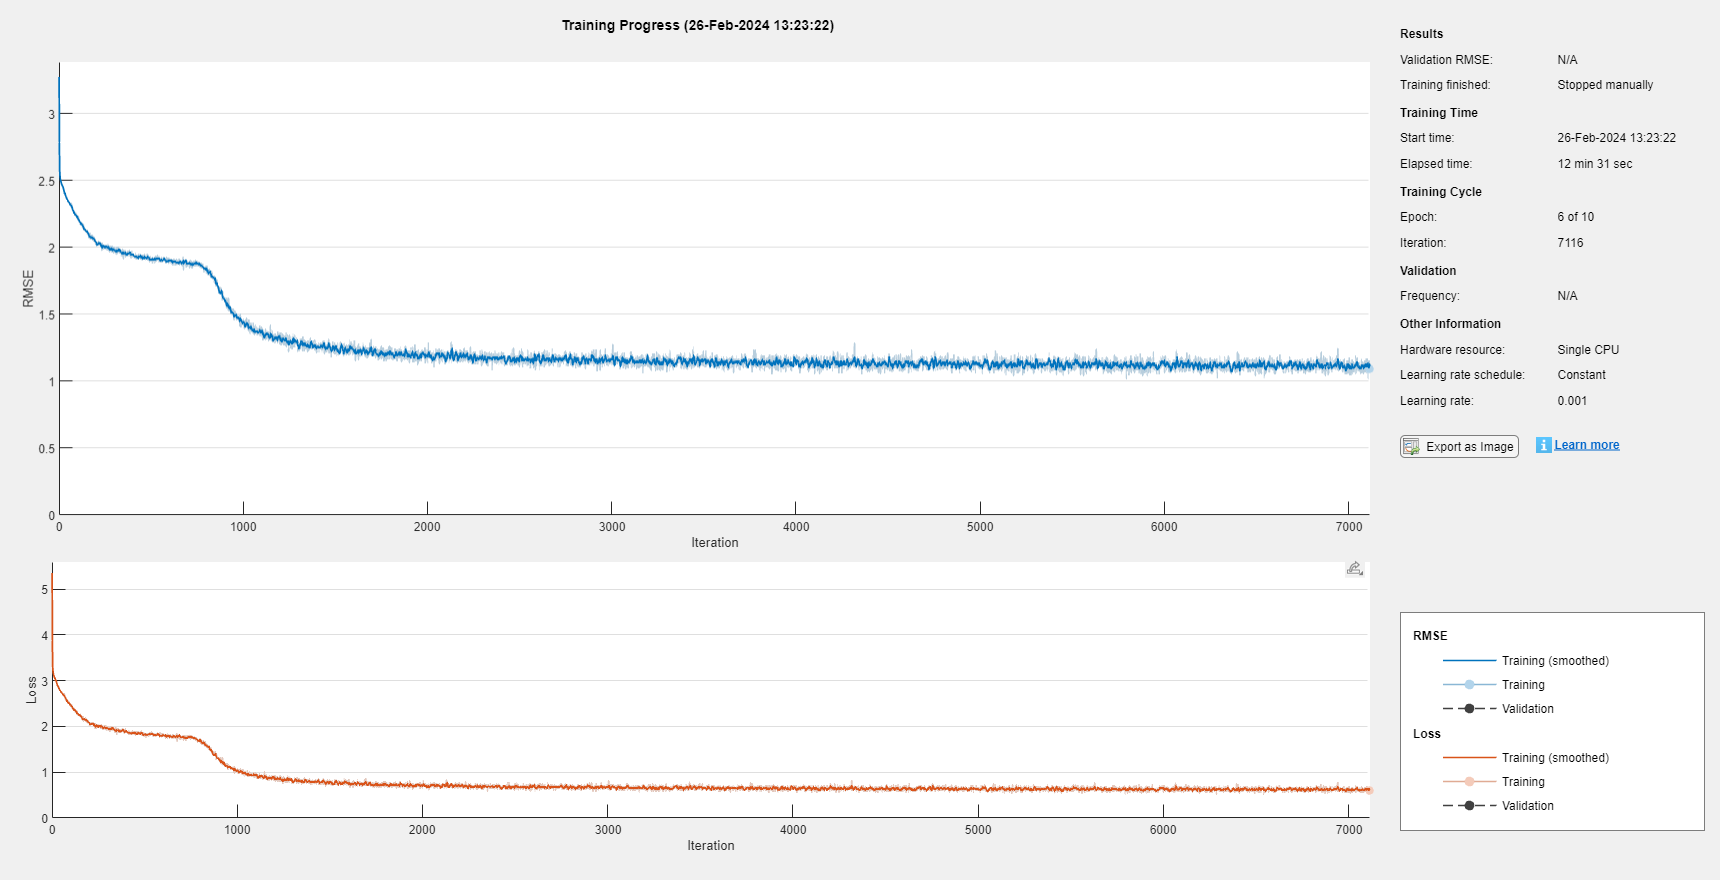

crn_network =   SeriesNetwork with properties:

         Layers: [23×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}


crn_network = trainNetwork(dsTrain, layers_CRN, options)

Sigmoid is used.

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |         3.14 |          4.9 |          0.0010 |
|       1 |          50 |       00:00:06 |         2.26 |          2.6 |          0.0010 |
|       1 |         100 |       00:00:10 |         2.12 |          2.3 |          0.0010 |
|       1 |         150 |       00:00:14 |         2.03 |          2.1 |          0.0010 |
|       1 |         200 |       00:00:18 |         1.97 |          1.9 |          0.0010 |
|       1 |         250 |       00:00:22 |         1.95 |          1.9 |          0.0010 |
|       1 |         300 |       00:00:26 |         1.94 |         

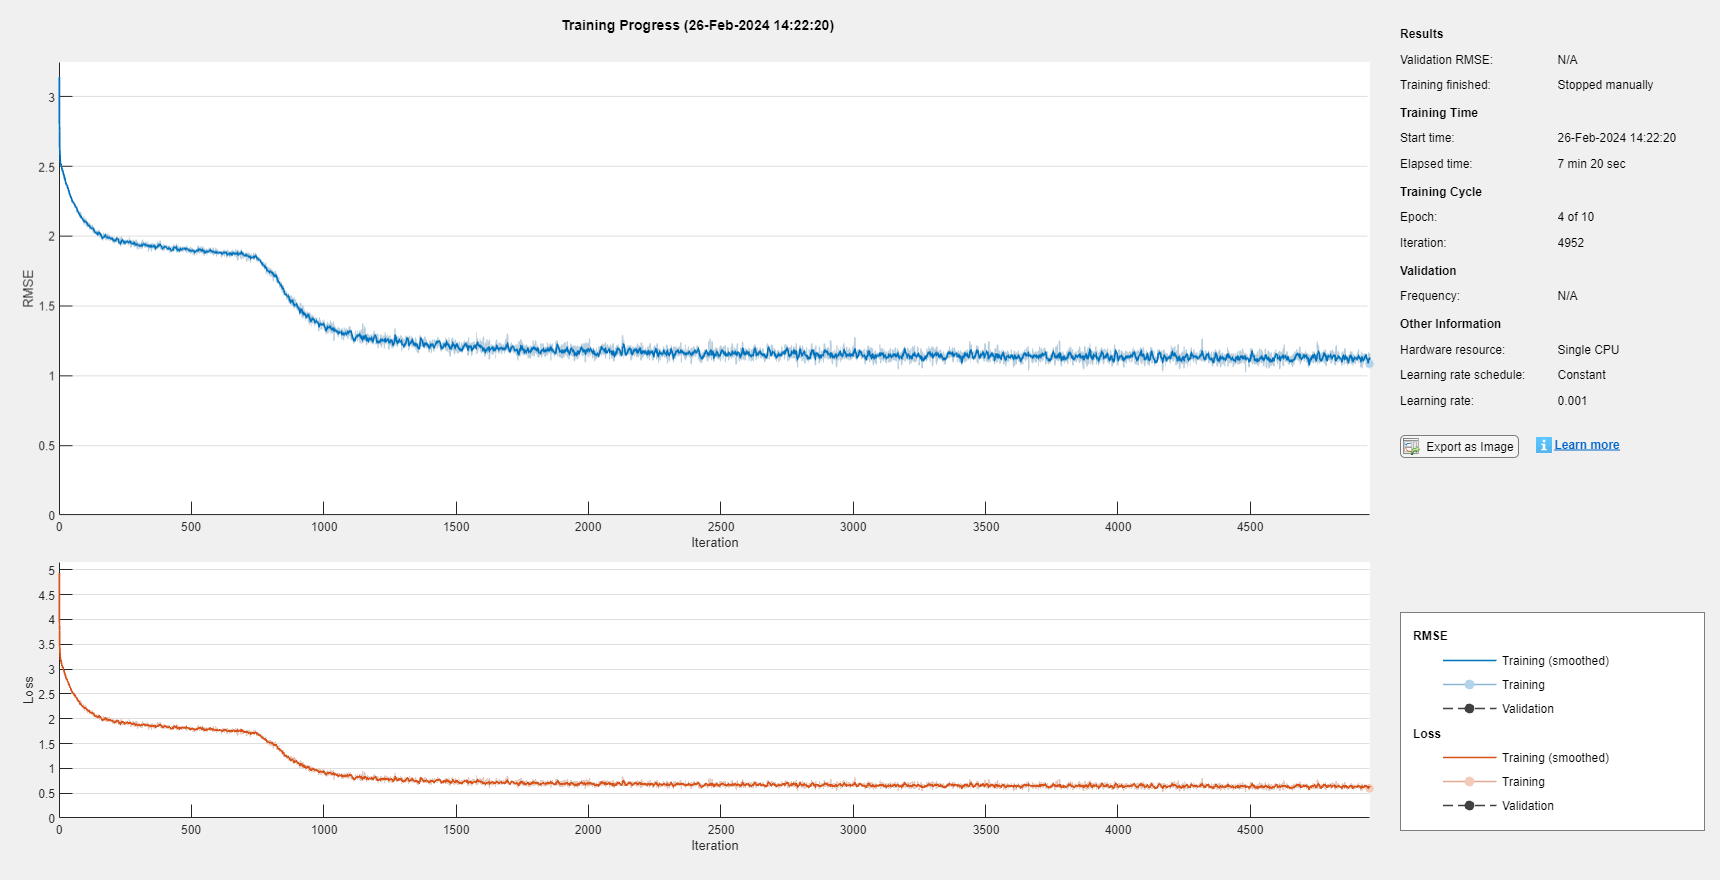

crn_network =   SeriesNetwork with properties:

         Layers: [23×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}


crn_network = trainNetwork(dsTrain, layers_CRN, options)

Below is a mess

r_learned = predict(crn_network, X_Test(:, end).').';

figure;
plot(r_learned);

figure;
plot(Y_Test(:, end));

a = dsTrain.read()

a = 1×2 cell array
    {4×4×2 double}    {14×1 double}


a{2}

ans =     1.0000
    0.3477
   -0.7582
   -0.8749
    0.1498
    0.9791
    0.5311
         0
   -0.9376
   -0.6520


YPred = predict(crn_network, X_Test).';
E = 360000;
avg_rmse = 0;
for i = 1:E
    avg_rmse = avg_rmse + rmse(YPred(:, i), Y_Test(:, i));
end
avg_rmse = avg_rmse / E

avg_rmse = single
0.1755

r_learned = YPred(:, end);
r = r_learned(1:N) + 1i * r_learned(N+1:end);
R_learned = toeplitz(r)

R_learned = 7×7 single matrix
   1.0001 - 0.0062i  -0.2368 - 0.7901i  -0.6935 + 0.5237i   0.7655 + 0.6006i   0.4817 - 0.7185i  -0.7175 - 0.1703i  -0.0716 + 0.8640i
  -0.2368 + 0.7901i   1.0001 - 0.0062i  -0.2368 - 0.7901i  -0.6935 + 0.5237i   0.7655 + 0.6006i   0.4817 - 0.7185i  -0.7175 - 0.1703i
  -0.6935 - 0.5237i  -0.2368 + 0.7901i   1.0001 - 0.0062i  -0.2368 - 0.7901i  -0.6935 + 0.5237i   0.7655 + 0.6006i   0.4817 - 0.7185i
   0.7655 - 0.6006i  -0.6935 - 0.5237i  -0.2368 + 0.7901i   1.0001 - 0.0062i  -0.2368 - 0.7901i  -0.6935 + 0.5237i   0.7655 + 0.6006i
   0.4817 + 0.7185i   0.7655 - 0.6006i  -0.6935 - 0.5237i  -0.2368 + 0.7901i   1.0001 - 0.0062i  -0.2368 - 0.7901i  -0.6935 + 0.5237i
  -0.7175 + 0.1703i   0.4817 + 0.7185i   0.7655 - 0.6006i  -0.6935 - 0.5237i  -0.2368 + 0.7901i   1.0001 - 0.0062i  -0.2368 - 0.7901i
  -0.0716 - 0.8640i  -0.7175 + 0.1703i   0.4817 + 0.7185i   0.7655 - 0.6006i  -0.6935 - 0.5237i  -0.2368 + 0.7901i   1.0001 - 0.0062i


R

R =    2.5687 + 0.0000i  -0.2422 + 0.8878i   0.4403 + 0.9174i   0.1222 - 1.0032i
  -0.2422 - 0.8878i   2.5536 + 0.0000i   0.7272 - 0.7020i  -0.9798 + 0.1643i
   0.4403 - 0.9174i   0.7272 + 0.7020i   2.6065 + 0.0000i  -0.9320 - 0.4532i
   0.1222 + 1.0032i  -0.9798 - 0.1643i  -0.9320 + 0.4532i   2.5852 + 0.0000i


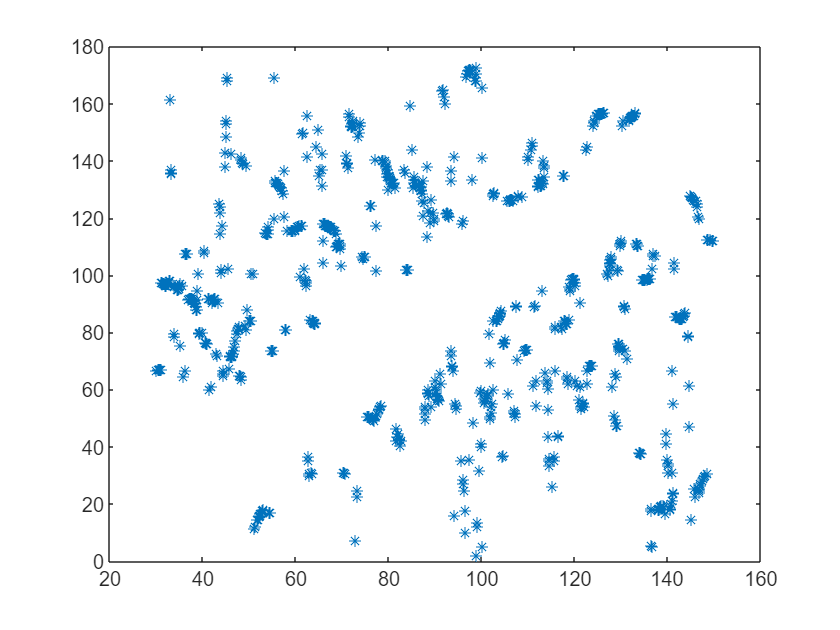

noOfTrial = 1000;
true_doa = zeros(1, noOfTrial);
pred_doa = zeros(1, noOfTrial);
for i = 1:noOfTrial
    doa = rand * 120 + 30;
    A = DOA.Array_Manifold(0.5, sensor_locations, doa);
    s = DOA.Source_Generate(K, 1000);
    SNR_dB = 10;
    n = DOA.Noise_Generate(SNR_dB, M, 1000);
    y = A * s + n;
    R_ohm = (1 / 1000) * (y * y');
    input = zeros(M, M, 2);
    input(:, :, 1) = real(R_ohm);
    input(:, :, 2) = imag(R_ohm);

    output = predict(crn_network, input).';
    r = output(1:N) + 1i * output(N+1:end);
    R = toeplitz(r).';
    % [ss_sla, angles] = DOA.MUSIC(K, 0.5, R_ohm, sensor_locations);
    % plot(angles, ss_sla);
    [ss_ula, angles] = DOA.MUSIC(K, 0.5, R);
    % plot(angles, ss_ula);
    [~, idx] = max(ss_ula);
    pred_doa(i) = angles(idx);
    true_doa(i) = doa;
end
plot(true_doa, pred_doa, '*')

a = [5; 5; 5];
b = [4; 3; 3];
rmse(a, b)^2

ans = 3.0000

YPred = classify(crn_network, X_Test);
YValidation = dsTest.Labels.';
accuracy = sum(YPred==YValidation)/numel(YValidation)

R = r2R(r);
ss = DOA.MUSIC(2, 0.5, R, sensor_locations);
plot(0:0.5:180, ss);

R = r2R(r_learned);
ss = DOA.MUSIC(2, 0.5, R, sensor_locations);
plot(0:0.5:180, ss);

possible_angles = linspace(80, 100, 210);
P = length(possible_angles);
A_star = zeros(M2, P);
for p = 1:P
    A_star(:, p) = exp(1i * pi * (sensor_locations).' * cosd(possible_angles(p)));
end
A_tilda = DOA.khatri_rao(conj(A_star), A_star);

c = R(:);

ksa = A_tilda' * c;
figure;
plot(possible_angles, ksa);

function R = r2R(r)
vecSize = length(r);
% M = sqrt(vecSize + 0.25) + 0.5;
M = sqrt(vecSize);
split_idx = (M+1)*M/2; 
re_r = r(1:split_idx);
im_r = r(split_idx+1:end);
split_idx = 0;
for i = M:-1:1
    im_r = [im_r(1:split_idx); 0; im_r(split_idx+1:end)];
    split_idx = split_idx + i;
end
r2 = re_r + 1i * im_r;
R = zeros(M);
for i = 1:M
    split_idx = M-i+1;
    R(i, i:M) = r2(1:split_idx);
    r2 = r2(split_idx+1:end);
end
R = R + R';
for i = 1:M
    R(i, i) = R(i, i) / 2;
end
end
